% generate figure 5
% dependence: initRSG2prior, v2struct

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

=fig5B=


H
# neurons: 533
# neurons: 535
G
# neurons: 639
# neurons: 636


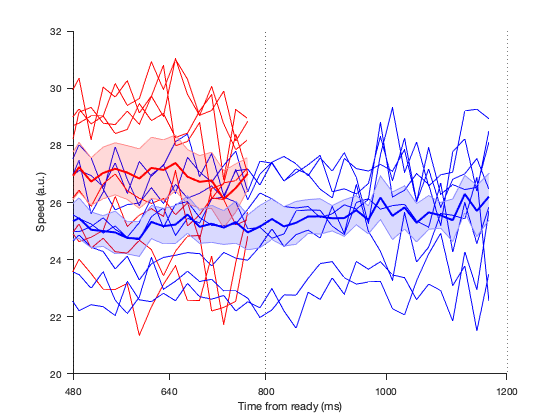

plot_speed(S); % fig5B

===== trajKS_set2IC_EL_G.mat =====
optimD: 8
===== trajKS_set2IC_EL_H.mat =====
optimD: 5
===== trajKS_set2IC_ER_G.mat =====
optimD: 7
===== trajKS_set2IC_ER_H.mat =====
optimD: 6
===== trajKS_set2IC_HL_G.mat =====
optimD: 6
===== trajKS_set2IC_HL_H.mat =====
optimD: 6
===== trajKS_set2IC_HR_G.mat =====
optimD: 6
===== trajKS_set2IC_HR_H.mat =====
optimD: 6


ans = 0.9176

ans = 0.1337

=fig5D=


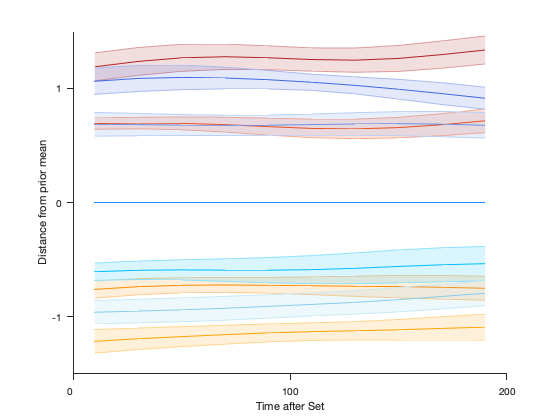


plot_distance_fromSet(S); % fig5D


plot_distance_fromGo(S); % fig5F: done by Nico

function plot_distance_fromGo(S) % fig5F

end

function plot_distance_fromSet(S) % fig5D
v2struct(S);
cd(psthDir);
load pplot.mat; % pplot.cmap for separate figure

idUseLowDim=1; % for angle

% plot
cmapPr=[rgb('FireBrick'); rgb('RoyalBlue'); rgb('DarkGreen')]; %
cmapRot=[rgb('DeepPink'); rgb('Aqua')];
msize=4; % 10; % 4; % 6; % 2;
msize2=1;
lw=.75;% 1.2; % 1; % 3; % 1.5;
lw2=2;
cmapMat=[tmpCmap{1,1}; tmpCmap{2,1}];

%% main
d=dir('trajKS_set2IC_*.mat'); % prior*_supportOnly.mat'); % IC specific % _bin20_smth40
nDS=length(d);

load(d(1).name,'binSize','durIC');
nT=round(durIC/binSize);

% distance matrix
x=nan(nDS,nTspp+nTspp,nT); % ref: short800
y=nan(nDS,nPr,nTspp,nT); % ref: mean of each prior

m=nan(nDS,nPr,nTspp); % magnitude
a=nan(nDS,nTspp+nTspp); % angle bewteen two priors - ref: short800

for iDS=1:nDS
    
%     disp(['===== ' d(iDS).name ' =====']);
    load(d(iDS).name); % binSize smthWidth optimD use_sqrt proj_matrix keep_neurons D eigenvalues meanPSTH
%     disp(['optimD: ' num2str(optimD)]);
    
    dsName=d(iDS).name(15:18);
    iAnimalNm=d(iDS).name(18);
    if strcmp(iAnimalNm,animalNm{1}), iAnimal=1; else iAnimal=2; end
    if strcmp(dsName(1:2),'ER'), iCond=1; elseif strcmp(dsName(1:2),'EL'), iCond=2; elseif strcmp(dsName(1:2),'HR'), iCond=3; else iCond=4; end
    
    nPC=size(D(1).data,1);
    
    if idUseLowDim
        nPCangle=3;
    else
        nPCangle=nPC;
    end
    
    % ref: short800
    ref=D(nTspp).data(1:nPC,:); % [nPC x #time]
    tmp=cat(3,D.data); % [nPC x #time x #trajectories]
    x(iDS,:,:)=squeeze(sqrt(sum((tmp-ref).^2,1)))';  % [#time x #trajectories]'
    
    % ref: mean of each prior
    for iPr=1:nPr
        ref=D((iPr-1)*nTspp+round(nTspp/2)).data(1:nPC,:); % [nPC x #time]
        tmp=cat(3,D((iPr-1)*nTspp+[1:nTspp]).data); % [nPC x #time x #trajectories]
        y(iDS,iPr,:,:)=squeeze(sqrt(sum((tmp-ref).^2,1)))';  % [#time x #trajectories]'
    end
    
    % magnitude
    for iPr=1:nPr
        tmp=cat(3,D((iPr-1)*nTspp+[1:nTspp]).data); % [nPC x #time x #trajectories]
%         m(iDS,iPr,:)=sqrt(sum((tmp(:,end,:)-tmp(:,1,:)).^2,1)); % distance between initial & end points
        m(iDS,iPr,:)=sqrt(sum(mean(diff(tmp,1,2).^2,2),1)); % mean length?
    end
    
    % angle % ref: short800
    ref=D(nTspp).data(1:nPCangle,end)-D(nTspp).data(1:nPCangle,1); % [nPC x 1/#time]
    tmp=cat(3,D.data); % [nPC x #time x #trajectories]
    tmp=tmp(1:nPCangle,end,:)-tmp(1:nPCangle,1,:);
    for iTmp=1:size(tmp,3)
        a(iDS,iTmp)=estAngle(ref(:),squeeze(tmp(:,1,iTmp)));
    end
    
end % for iDS=1:nDS

% stat
% do regression as f(time) 8datasets x 2pr x 4 non-middle ts
slope=nan(nDS,nPr,nTspp);
for iDS=1:nDS
    for iPr=1:nPr
        for iT=1:nTspp
            tmpB=regress(squeeze(y(iDS,iPr,iT,:)),[[1:nT]' ones(nT,1)]);
            slope(iDS,iPr,iT)=tmpB(1);
        end
    end
end
tmpSlope=slope(:,:,1); signrank(tmpSlope(:)); % minimum ts
tmpSlope=slope(:,:,end); signrank(tmpSlope(:)); % max ts

%% avg across data sets
mx=squeeze(mean(x,1)); % [ts x time]
my=squeeze(mean(y,1)); % [pr x ts x time]

sx=squeeze(sem(x,1)); % [ts x time]
sy=squeeze(sem(y,1)); % [pr x ts x time]

% fig5d %%%%%
disp('=======');
disp('=fig5D=');
disp('=======');
figure; ha;box off;  % distance from prior mean
tmpX=binSize/2+binSize*([1:nT]-1);
for iPr=1:nPr
    for iT=1:nTspp
        if iT>nTspp/2 % flip sign for long
%             plot(1:nT,-squeeze(my(iPr,iT,:)),'linewidth',2,'color',tmpCmap{iPr,1}(iT,:));
            shadedErrorBar(tmpX,-squeeze(my(iPr,iT,:)),squeeze(sy(iPr,iT,:)),{'linewidth',lw,'color',tmpCmap{iPr,1}(iT,:)},1);
        else
%             plot(1:nT,squeeze(my(iPr,iT,:)),'linewidth',2,'color',tmpCmap{iPr,1}(iT,:));
            shadedErrorBar(tmpX,squeeze(my(iPr,iT,:)),squeeze(sy(iPr,iT,:)),{'linewidth',lw,'color',tmpCmap{iPr,1}(iT,:)},1);
        end
    end
end
xlabel('Time after Set');
ylabel('Distance from prior mean');
set(gca,'xtick',[0 durIC/2 durIC],'xticklabel',[0 durIC/2 durIC],'tickDir','out','tickLength',[0.015 0.015],'ytick',[-1:1:1]);
xlim([0 durIC]);
% applytofig4keynote;

end


function plot_speed(S) % fig5B
v2struct(S);

binSize=20;
smthWidth=40;

overlapT=800;

cd(psthDir);

condNm={'ER','EL','HR','HL'};
condNm2={'Eye Left','Eye Right','Hand Left','Hand Right'};
nCond=numel(condNm);

% key data
dist=cell(length(animalNm)*nEH*nTarg,1);
distPC=cell(length(animalNm)*nEH*nTarg,1);

% speed
idAvgBeforeSp=0; % 0; % 1;
idUseStencil=0; % 1; % 0;
nP=5; % 3; % 5; % 3;
if idUseStencil==0, nP=1; end;
idSanityCheck=0; % 1; % 0;
sp=cell(length(animalNm)*nEH*nTarg,2); % last for ts/tp separately; aligned to ready/set
smthWidthSp= 20; % 80; % 40; % 20; % if 0, no smoothing

% main
disp('=======');
disp('=fig5B=');
disp('=======');
figure; ha; % speed(whole ts): short vs long

for iAnimal=1:length(animalNm)
    %% in full state space
    load(['PSTH_periSet_' animalNm{iAnimal} '_full_SUMU.mat']); % PSTH_t_s_H_SUMU.mat'); % D(40) nTrialExc tBuffer
    disp(animalNm{iAnimal});
    
    % find id for overlap among 40 conditions
    tmpId=nEH*nTarg*(nTs-1)+[1:8]; % 17:24  short800ER>EL>HR>HL>Long800...
    tmpD=D(tmpId);
    
    % smoothing & binning
    tmpD=smoothBin(tmpD,binSize,smthWidth);
    
    %% SPEED
%     disp('===== speed =====');
    % idAvgBeforeSp==0: binningSmoothing PSTH > speed > avgAcrossTs with attrition
    % smoothing & binning
    Dsp=smoothBin(D,binSize,smthWidthSp);
    for iHE=1:nEH
        for iTarg=1:nTarg
            iEHTarg=(iHE-1)*nTarg+iTarg; % 1:4
            iTmp=(iAnimal-1)*nEH*nTarg+iEHTarg; % 1:8
            sp{iTmp,1}=cell(1,1); % ts
            sp{iTmp,2}=cell(1,1); % tp
            
            for iD=iEHTarg:nCond:length(Dsp) % for each pr/ts
                tmpTs=Dsp(iD).epochStarts(2); % ts/binSize
                if idUseStencil
                    tmpSp1=sqrt(sum(deriv(Dsp(iD).data(:,1:tmpTs)',binSize/1000,1,nP).^2,1)); % [1 x time-1]
                    tmpSp2=sqrt(sum(deriv(Dsp(iD).data(:,tmpTs:end)',binSize/1000,1,nP).^2,1)); % [1 x time-1]
                else
                    tmpSp1=sqrt(sum(diff(Dsp(iD).data(:,1:tmpTs),1,2).^2,1)); % [1 x time-1]
                    tmpSp2=sqrt(sum(diff(Dsp(iD).data(:,tmpTs:end),1,2).^2,1)); % [1 x time-1]
                end
                %                 if iD==1 % isempty(sp{iTmp,1})
                %                     sp{iTmp,1}=tmpSp1(:)';
                %                 else
                sp{iTmp,1}=[sp{iTmp,1}; tmpSp1(:)'];
                %                 end
                %                 if iD==1 % isempty(sp{iTmp,2})
                %                     sp{iTmp,2}=tmpSp2(:)';
                %                 else
                sp{iTmp,2}=[sp{iTmp,2}; tmpSp2(:)'];
                %                 end
            end % iD
            
            sp{iTmp,1}=sp{iTmp,1}(2:end);
            sp{iTmp,2}=sp{iTmp,2}(2:end);
            
        end % iTarg
    end % iHE
end % iAnimal

%% plot speed
% ts (short vs long)
mV{1}=cell(1,1); mV{2}=cell(1,1);
for i=1:size(sp,1) % 1:size(sp,1)/2 %(1+size(sp,1)/2):size(sp,1) %  1:size(sp,1)
    try
        vTs=fillNanCell(sp{i,1}); % [10ts x time]
    catch
        disp();
    end
    vTss=nanmean(vTs(1:nTspp,:),1); % [1 x time]
    vTsl=nanmean(vTs(nTspp+[1:nTspp],:),1); % [1 x time]
    mV{1}=[mV{1}; vTss];mV{2}=[mV{2}; vTsl];
    if idUseStencil
        tmpT=(binSize*round(nP/2)-binSize/2)+[0:binSize:(binSize*(length(vTss)-1))]; % (binSize/2)+[0:binSize:(binSize*(length(vTss)-1))];
        plot(tmpT,vTss,'r-');
        tmpT=(binSize*round(nP/2)-binSize/2)+[0:binSize:(binSize*(length(vTsl)-1))]; % (binSize/2)+[0:binSize:(binSize*(length(vTsl)-1))];
        plot(tmpT,vTsl,'b-');
    else
        tmpT=(binSize/2)+[0:binSize:(binSize*(length(vTss)-1))];
        plot(tmpT,vTss,'r-');
        tmpT=(binSize/2)+[0:binSize:(binSize*(length(vTsl)-1))];
        plot(tmpT,vTsl,'b-');
    end
end
% plot avg
mmv1=fillNanCell(mV{1}); % [8data x time]
if idUseStencil
    tmpT=(binSize*round(nP/2)-binSize/2)+[0:binSize:(binSize*(size(mmv1,2)-1))]; % %(binSize/2)+[0:binSize:(binSize*(size(mmv1,2)-1))]; % 10:20:....
else
    tmpT=(binSize/2)+[0:binSize:(binSize*(size(mmv1,2)-1))]; % 10:20:....
end
shadedErrorBar(tmpT(:)',nanmean(mmv1,1),sem(mmv1,1,'omitnan'),{'-','color','r','linewidth',2},1); drawnow;
mmv2=fillNanCell(mV{2}); % [8data x time]
if idUseStencil
    tmpT=(binSize*round(nP/2)-binSize/2)+[0:binSize:(binSize*(size(mmv2,2)-1))]; %(binSize/2)+[0:binSize:(binSize*(size(mmv2,2)-1))]; % 10:20:....
else
    tmpT=(binSize/2)+[0:binSize:(binSize*(size(mmv2,2)-1))]; % 10:20:....
end
shadedErrorBar(tmpT(:)',nanmean(mmv2,1),sem(mmv2,1,'omitnan'),{'-','color','b','linewidth',2},1); drawnow;

xlim([T{1}(1) T{2}(end)])
plotVertical(gca,[T{1}(1) overlapT T{2}(end)],[]);
set(gca,'xtick',[0 T{1}(1:2:3) T{2}(1:2:end)],'tickdir','out','ticklength',[0.015 0.015]); %  overlapT overlapT+200]);
xlabel('Time from ready (ms)');
ylabel('Speed (a.u.)');
pause(0.5);

end % plot_speed

function D=smoothBin(D,binSize,smthWidth)
handles.binWidth=binSize;
handles.use_sqrt=0;

handles.kern=smthWidth;

m = mean([D.data],2) * 1000;
mean_thresh=1; % remove neurons with FR<1 sp/s
keep_neurons = m>=mean_thresh; %-Inf; %m >= mean_thresh; % -Inf; % mean_thresh; %%%%%
handles.keep_neurons=keep_neurons;
handles.mean_thresh=mean_thresh;
% disp(nnz(keep_neurons));

% Remove low firing rate neurons
for itrial = 1:length(D)
    D(itrial).data = D(itrial).data(handles.keep_neurons,:);
    D(itrial).id = D(itrial).id(handles.keep_neurons,:);
end
disp(['# neurons: ' num2str(size(D(1).data,1))]);

% Bin the spikes and use square root transform (use gpfa's pack)
if (handles.binWidth ~= 1 || handles.use_sqrt)
    [d(1:length(D)).spikes] = deal(D.data);
    for itrial = 1:length(D)
        d(itrial).trialId = itrial;
    end
    s = getSeq(d, handles.binWidth, 'useSqrt', handles.use_sqrt); % spike counts
    [D.data] = deal(s.y);
end

% Smooth data if necessary (automatically zero if GPFA selected)
for i = 1:length(D)
    D(i).data = smoother(D(i).data, handles.kern, handles.binWidth);
end

% convert into sp/s
for i = 1:length(D)
    D(i).data = D(i).data./handles.binWidth*1000;
end

% binning epochStarts
if length(D(i).epochStarts)>1
    for i = 1:length(D)
        D(i).epochStarts(2) = round(D(i).epochStarts(2)/handles.binWidth);
    end
end
end % smoothBin
